% ASEN 5044 HWK #3 
% Problem 1

l = 1.85; % length of rod
m = 2; % point mass
M = 4; % cart mass
g = 9.81; % gravity
dt = 0.05; % sampling interval
n = 301-1; % number of samples
tlist = 0:dt:15; % time sample matrix

A =[ 0,1,0,0;0,0 m*g/M,0; 0,0,0,1;0,0,g*(m+M)/(M*l),0];
B = [0;1/M;0;1/(l*M)];
C = [1,0,-l,0];
D = zeros(1);

Ctilde = zeros(1,4); % zero matrix to compute DT model
Atilde = [A,B;Ctilde,D]; % compiled matrix
FG=expm(Atilde*dt); % DT conversion
F = FG(1:4,1:4);
G = FG(1:4,5:5);
H = C;
M = D;

lambda = eig(A);
lambda_norm = abs(lambda);

% assign data variables
output = importdata("midterm1problem1data.mat");
ydata = output.yNLhist(1:n);
gains = output.Kc;

% build observability matrix [HF,HFF,...]

Obs = [];
for i = 1 : n
    Obs = [Obs;H*F^(i);];
end
rank(Obs(1:4,1:4)) % rank 4 so full column rank

ans = 4


% find initial conditions
% we know that y(1) = Hx(1)
% so x(1) = pinv(H)*y(1)
x1 = pinv(H)*ydata(1);
% extrapolate first u value
u=-gains*x1;

% x(1) = Fx(0) + Gu so x(0) = F^1(x(1)-Gu)
x0 = inv(F)*(x1-G*u);
% u(0) = -gains*x0
u(1) = -gains*x0

u = 19.1065

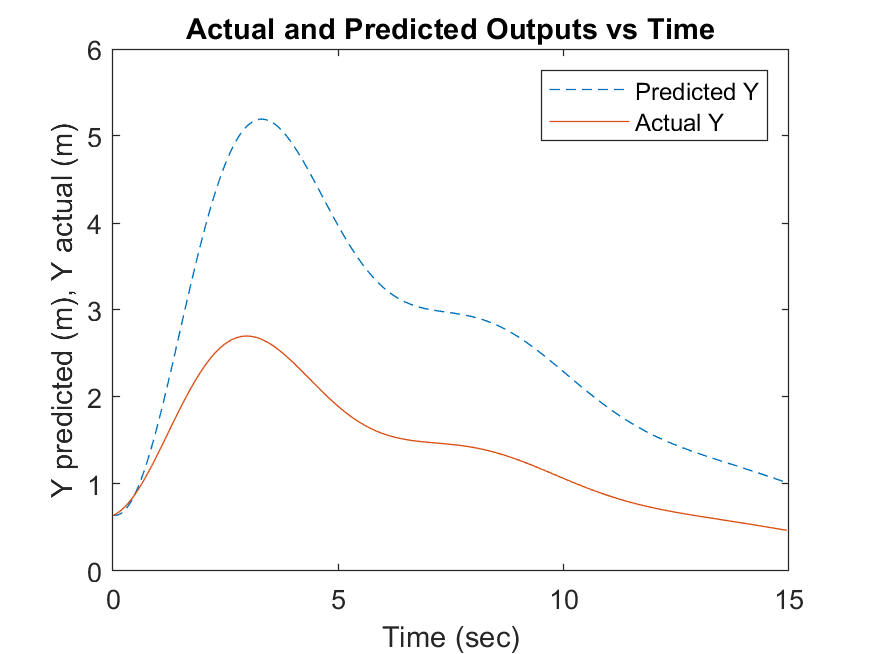

x_1 = F*x0 + G*u(1); % get first x values
y_1 =  H*x_1; % y1 = z - lsin(theta)'
u(2) = -gains*x_1;
xdot = [x0,x_1];  %assign first xdot
ypred = y_1;  % assign first y prediction

for i=2:n
    u(i) = -gains*xdot(1:4,i-1);
    xdot(:,i) = F*xdot(:,i-1) + G*u(i)';
    ypred(:,i) = H*xdot(:,i);

end

f2=figure;
plot(tlist(1:n),ypred,"--",tlist(1:n),ydata')
title('Actual and Predicted Outputs vs Time')
xlabel('Time (sec)')
ylabel('Y predicted (m), Y actual (m)')
legend({'Predicted Y', 'Actual Y'},'Location','northeast')

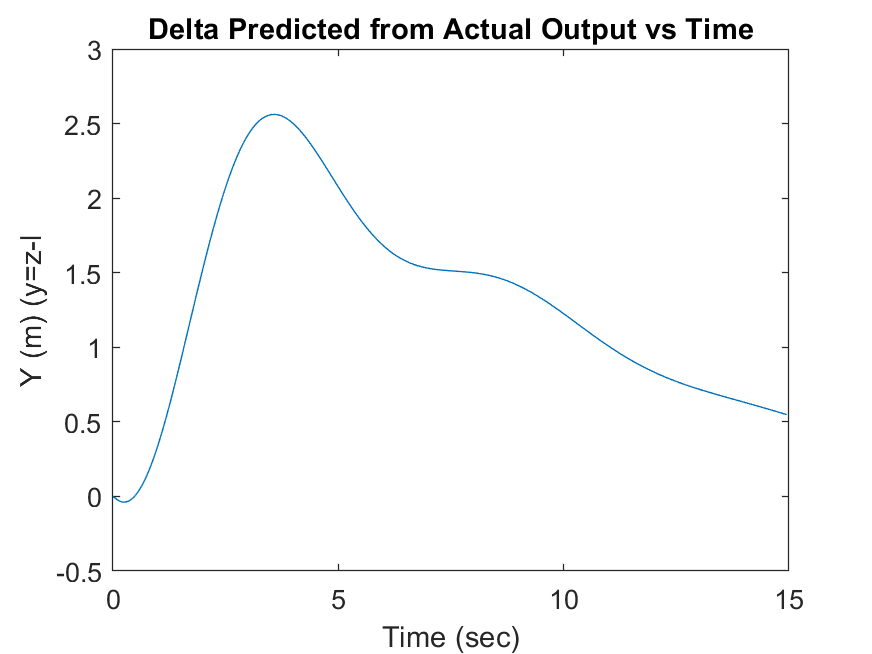


f2=figure;
plot(tlist(1:n),ypred-ydata')
title('Delta Predicted from Actual Output vs Time')
xlabel('Time (sec)')
ylabel('Y (m) (y=z-l')

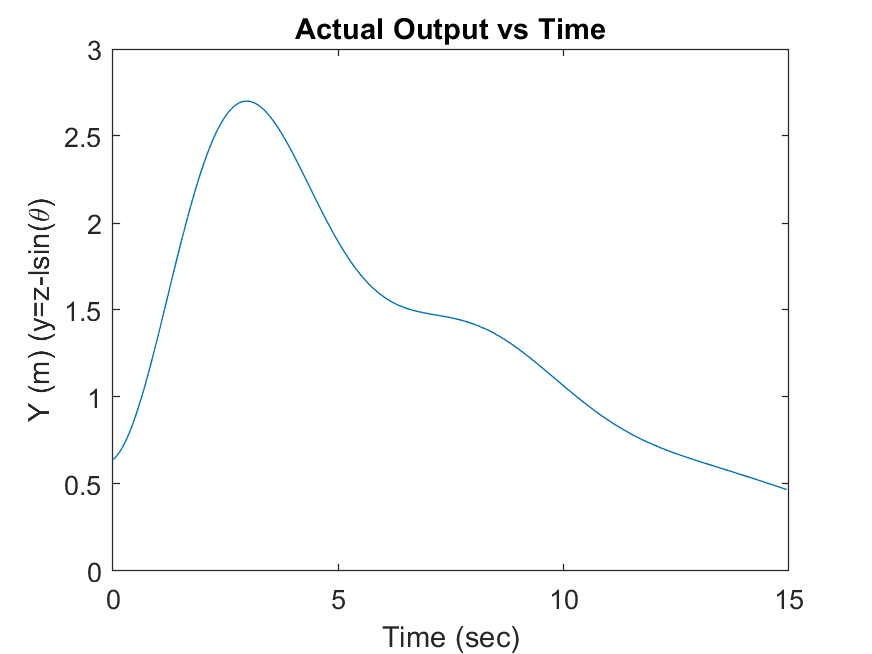

%legend({'Predicted Y' },'Location','northwest')

f3=figure;
p=plot(tlist(1:n),ydata');
title("Actual Output vs Time");
ylabel('Y (m) (y=z-lsin(\theta)');
xlabel('Time (sec)')

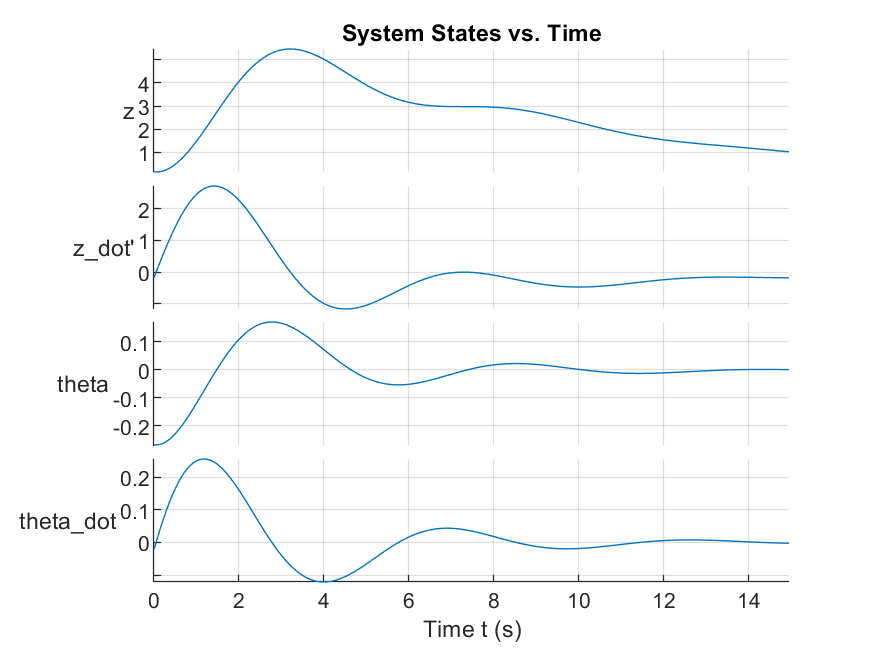

%legend({'Y_1','Y_2'}, 'Location','northwest')

f1=figure;
s=stackedplot(tlist(1:n), xdot');
xlabel('Time t (s)');
s.DisplayLabels={'z', 'z_dot''', 'theta', 'theta_dot'};
ax = findobj(s.NodeChildren, 'Type','Axes');
set([ax.YLabel],'Rotation',90,'HorizontalAlignment', 'Center', 'VerticalAlignment', 'Bottom')
title('System States vs. Time');
grid on;